minimize $f(x) = -x_1^4 - 2x_2^4 - x_3^4 - x_1^2x_2^2 - x_1^2x_3^2$

subject to $a_1(x) = x_1^4 + x_2^4 + x_3^4 - 25 = 0$

                 
$$a_2(x) = 8x_1^2 + 14x_2^2 + 7x_3^2 - 56 = 0$$


f = @(x) -x(1)^4 - 2*x(2)^4 - x(3)^4 - x(1)^2*x(2)^2 ...
    - x(1)^2*x(3)^2;
a1 = @(x) x(1)^4 + x(2)^4 + x(3)^4 - 25;
a2 = @(x) 8*x(1)^2 + 14*x(2)^2 + 7*x(3)^2 - 56;
ax = @(x) [a1(x); a2(x)]

ax = function_handle with value:
    @(x)[a1(x);a2(x)]


syms x_1 x_2 x_3  lambda_1 lambda_2

xs0 = [x_1; x_2; x_3] ;
lams0 = [lambda_1; lambda_2];
As = jacobian(ax(xs0), xs0);

rd = -gradient(f(xs0), xs0) + As'*lams0;
Ws = hessian(f(xs0), xs0) + hessian(a1(xs0), xs0)*lams0(1) + ...
    hessian(a2(xs0), xs0)*lams0(2);

kmax = 100;
x = zeros(3, kmax);
lam = zeros(2, kmax);
x0 = [3, 1.5, 3]; 
x(:,1) = x0; 
lam0 = [1, 1]; 
lam(:,1) = lam0;
dx = 100*ones(3,1);
k = 1;

while (norm(dx) >= 1e-8) && (k <= kmax)
    [xnew, lamnew] = Qp(f, ax, x(:,k), lam(:,k), xs0);
    dx = x(:,k) - xnew;
    x(:,k+1) = xnew;
    lam(:,k+1) = lamnew;
    k = k + 1;
end
xp = x(:,1:k);
lamp = lam(:,1:k); 
N = size(xp, 2);
nv = 1:N;
a1p = zeros(1,N); a2p = zeros(1,N); fp = zeros(1,N);
for i = 1:size(xp,2)
    a1p(i) = a1(xp(:,i));
    a2p(i) = a2(xp(:,i));
    fp(i) = f(xp(:,i));
end
disp(xp)

    3.0000    2.2217    1.4807    1.8203    2.0870    1.7582    1.8273    1.8767    1.8741    1.8741    1.8741
    1.5000    0.1236    0.5961    0.3182    0.1896    0.3168    0.4630    0.4568    0.4659    0.4658    0.4658
    3.0000    2.6350    2.4290    2.0990    1.7795    2.1323    1.9580    1.8882    1.8847    1.8847    1.8847



disp(fp); disp(k)

 -273.3750 -106.9157  -53.5869  -45.3443  -42.9519  -44.6158  -39.4563  -38.4947  -38.2858  -38.2848  -38.2848

    11



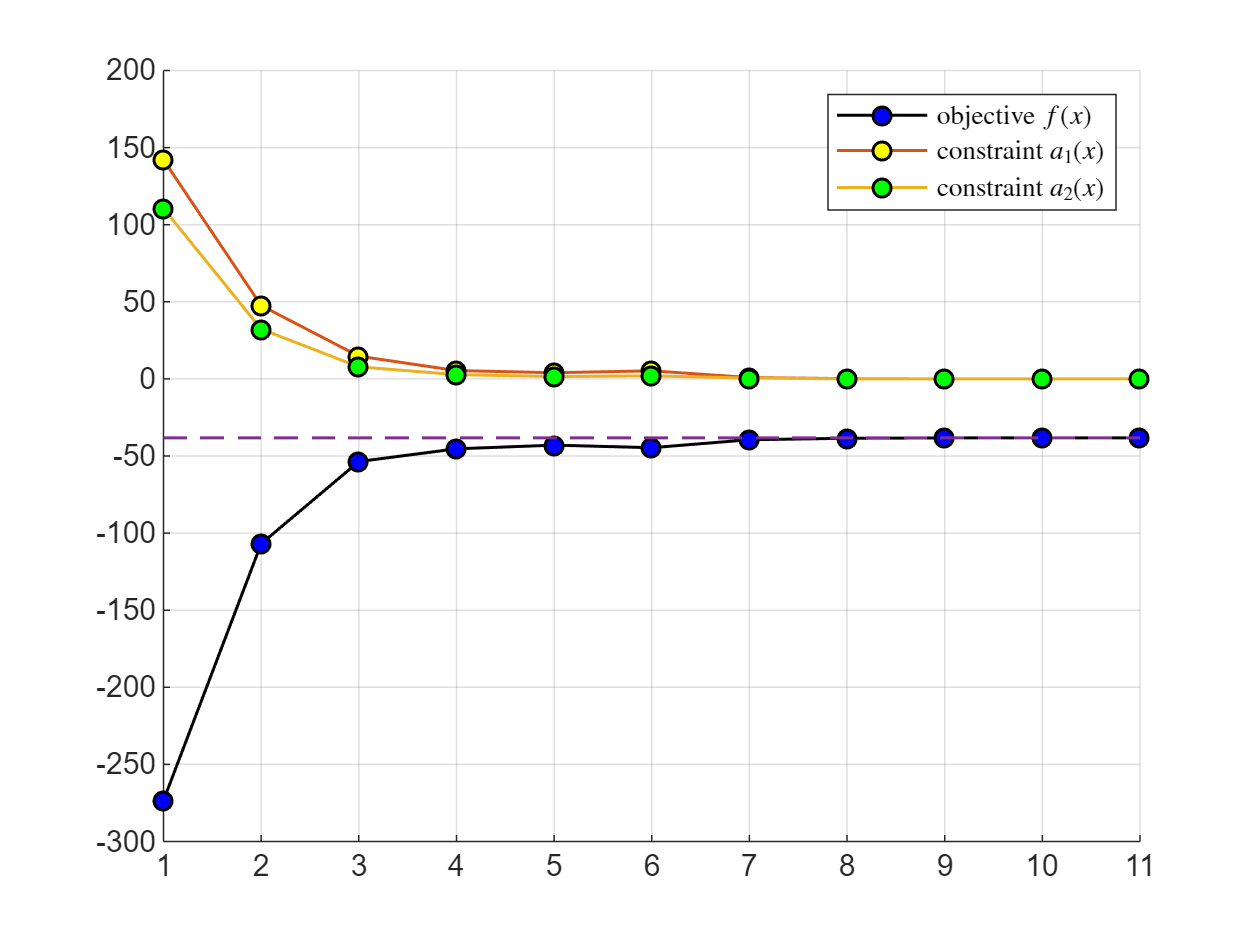

figure(1); clf;
hold on
plot(nv, fp,'ko-', 'LineWidth',1, 'MarkerFaceColor','blue');
plot(nv, a1p, 'o-', 'linewidth',1, 'MarkerFaceColor', 'yellow', 'MarkerEdgeColor','black');
plot(nv, a2p,'o-', 'linewidth', 1, 'markerfacecolor','g', 'MarkerEdgeColor','black');
plot(nv, fp(end)*ones(1,N),'--', 'linewidth', 1);
grid;
axis([1,k, -300, 200]);
h1 = legend('objective $f(x)$', 'constraint $a_1(x)$', 'constraint $a_2(x)$');
set(h1, 'Interpreter','latex');

hold off

function [xnew, lamnew] = Qp(f, ax, x0, lam0, xs0 )
    aax = ax(xs0); %a11 = aax(1); a22 = aax(2);
    %gks = gradient(f(xs0), xs0);
    As = jacobian(ax(xs0), xs0);
    rds = -gradient(f(xs0), xs0);%+ As'*lam0;
    %Ws = hessian(f(xs0), xs0) + hessian(aax(1), xs0)*lam0(1) + ...
    %    hessian(aax(2), xs0)*lam0(2);
    Ws = hessian(f(xs0), xs0);
    for i = 1:size(ax(xs0),1)
        Ws = Ws + hessian(aax(i), xs0)*lam0(i) ;
    end

    % change symbolic to numerical 
    Ak = double(subs(As, xs0, x0));
    rd = double(subs(rds, xs0, x0));
    rp = double(-ax(x0));
    %gk = double(subs(gks, xs0, x0));
    Wk = double(subs(Ws, xs0, x0));

    % calculation step
    dz = [Wk Ak'; Ak zeros(size(Ak,1), size(Ak',2))]\[rd; rp];
    dx = dz(1:size(x0,1));
    lam = dz(size(x0,1)+1:end,1);
    %disp(lam)
    %lam = -Ak'\((Wk)*dx + gk);

    xnew = x0 + dx; lamnew = lam;
end

%Wss = hessian(f(xs0), xs0);
%aa = ax(xs0)
%for i = 1:size(ax(xs0),1)
%    Wss = Wss +  hessian(aa(i), xs0)*lams0(i)
%end
%Ws = hessian(f(xs0), xs0) + hessian(a1(xs0), xs0)*lams0(1) + ...
%    hessian(a2(xs0), xs0)*lams0(2)
%Wss
%Ws
%Ws - Wss